## 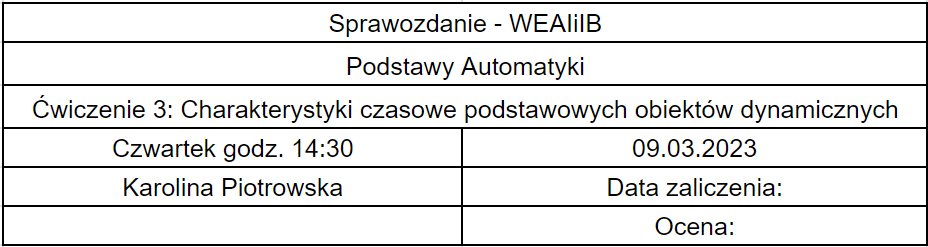

## Cele ćwiczenia

Ćwiczenie miało na celu wyznaczenie charakterystyk częstotliwościowych amplitudowo-fazowych oraz logarytmicznych modułu i fazy.

## Wstęp teoretyczny

Charakterystyki częstotliwościowe określają zachowanie elementu przy wszystkich częstitliwościach wymuszenia sinusoidalnego, podając stosunek amplitud odpowiedzi do wymuszenia oraz przesunięcie fazowe między odpowiedzią a wymuszeniem jako funkcje częstotliwości.

Charakterydstyka amplitudowo-fazowa to wykres transmitancji widmowej układu na płaszczyźnie zmiennej zespolonej. Charakterystyka częstotliwościowa logarytmiczna obrazuje logarytmiczną zależność amplitudy i fazy od częstotliwości i, w przeciwieństwie do poprzedniej, składa się z dwóch wykresów - dla amplitudy i fazy

## Przebieg laboratorium

### Obiekt inercyjny I rzędu

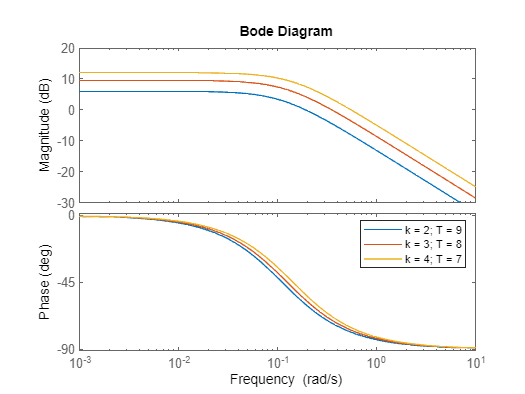

k1 = 2;
T1 = 9;
k2 = 3;
T2 = 8;
k3 = 4;
T3 = 7;

licz1 = [0, k1];
mian1 = [T1, 1];
licz2 = [0, k2];
mian2 = [T2, 1];
licz3 = [0, k3];
mian3 = [T3, 1];

bode(licz1, mian1)
hold on
bode(licz2, mian2)
bode(licz3, mian3)
hold off
legend('k = 2; T = 9', 'k = 3; T = 8', 'k = 4; T = 7')

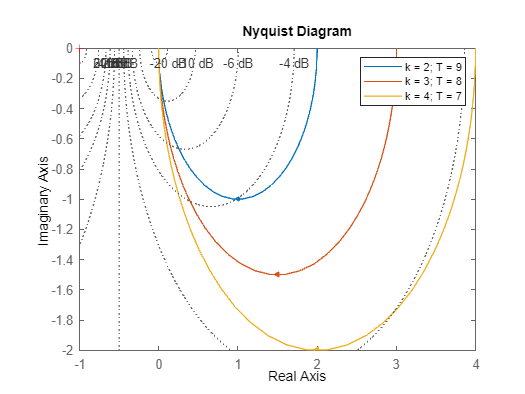


G1 = tf(licz1, mian1);
G2 = tf(licz2, mian2);
G3 = tf(licz3, mian3);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G1, plotoptions);
hold on
nyquist(G2, plotoptions);
nyquist(G3, plotoptions);
hold off
grid on
legend('k = 2; T = 9', 'k = 3; T = 8', 'k = 4; T = 7')

### Obiekt inercyjny II rzędu

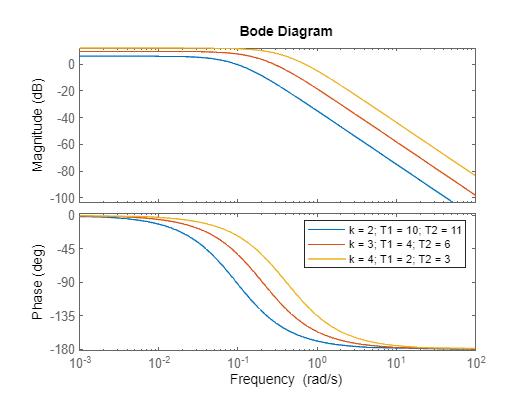

T11 = 10;
T12 = 11;
T21 = 4;
T22 = 6;
T31 = 2;
T32 = 3;

licz1 = [k1];
licz2 = [k2];
licz3 = [k3];

mian1 = [T11*T12, T11 + T12, 1];
mian2 = [T21*T22, T21 + T22, 1];
mian3 = [T31*T32, T31 + T32, 1];

bode(licz1, mian1)
hold on
bode(licz2, mian2)
bode(licz3, mian3)
hold off
legend('k = 2; T1 = 10; T2 = 11', 'k = 3; T1 = 4; T2 = 6', 'k = 4; T1 = 2; T2 = 3')

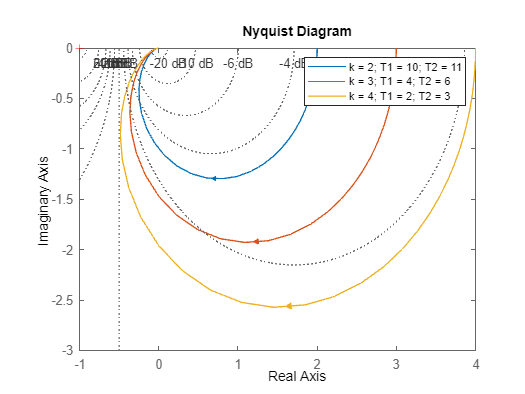


G1 = tf(licz1, mian1);
G2 = tf(licz2, mian2);
G3 = tf(licz3, mian3);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G1, plotoptions);
hold on
nyquist(G2, plotoptions);
nyquist(G3, plotoptions);
hold off
grid on
legend('k = 2; T1 = 10; T2 = 11', 'k = 3; T1 = 4; T2 = 6', 'k = 4; T1 = 2; T2 = 3')

### Obiekt oscylacyjny II rzędu

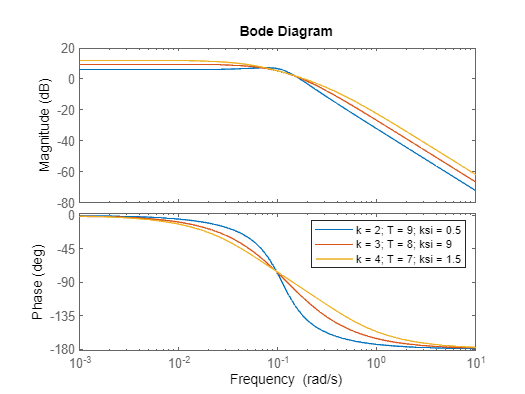

ksi1 = 0.5;
ksi2 = 1;
ksi3 = 1.5;

mian1 = [T1^2, 2*ksi1*T1, 1];
mian2 = [T2^2, 2*ksi2*T2, 1];
mian3 = [T3^2, 2*ksi3*T3, 1];

bode(licz1, mian1)
hold on
bode(licz2, mian2)
bode(licz3, mian3)
hold off
legend('k = 2; T = 9; ksi = 0.5', 'k = 3; T = 8; ksi = 9', 'k = 4; T = 7; ksi = 1.5')

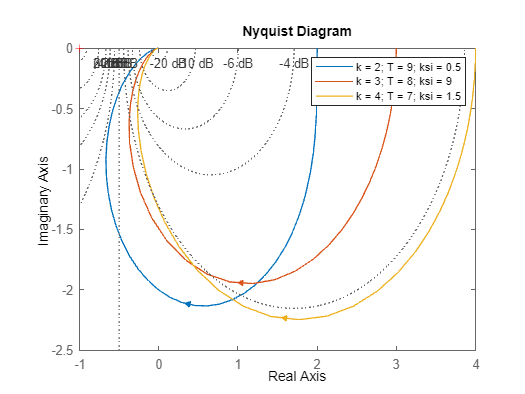


G1 = tf(licz1, mian1);
G2 = tf(licz2, mian2);
G3 = tf(licz3, mian3);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G1, plotoptions);
hold on
nyquist(G2, plotoptions);
nyquist(G3, plotoptions);
hold off
grid on
legend('k = 2; T = 9; ksi = 0.5', 'k = 3; T = 8; ksi = 9', 'k = 4; T = 7; ksi = 1.5')

### Obiekt całkujący z inercją I rzędu

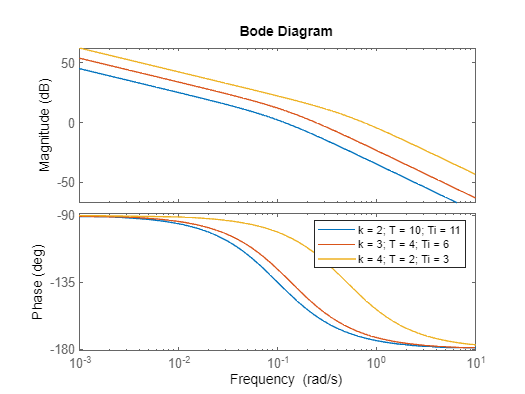

mian1 = [T11*T12, T12, 0];
mian2 = [T21*T12, T22, 0];
mian3 = [T31*T32, T32, 0];

bode(licz1, mian1)
hold on
bode(licz2, mian2)
bode(licz3, mian3)
hold off
legend('k = 2; T = 10; Ti = 11', 'k = 3; T = 4; Ti = 6', 'k = 4; T = 2; Ti = 3')

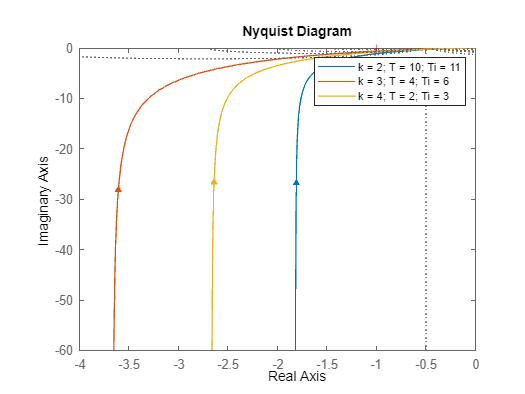


G1 = tf(licz1, mian1);
G2 = tf(licz2, mian2);
G3 = tf(licz3, mian3);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G1, plotoptions);
hold on
nyquist(G2, plotoptions);
nyquist(G3, plotoptions);
hold off
grid on
legend('k = 2; T = 10; Ti = 11', 'k = 3; T = 4; Ti = 6', 'k = 4; T = 2; Ti = 3')

### Obiekt różniczkujący rzeczywisty 

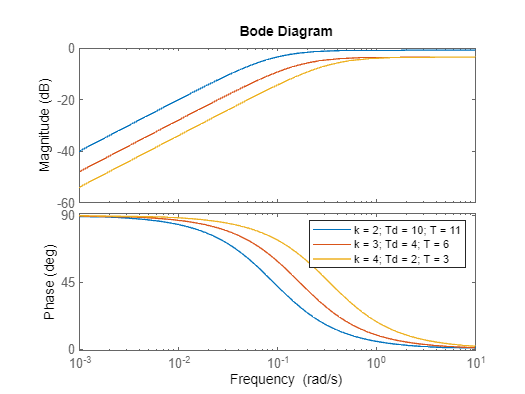

licz1 = [T11, 0];
licz2 = [T21, 0];
licz3 = [T31, 0];

mian1 = [T12, 1];
mian2 = [T22, 1];
mian3 = [T32, 1];

bode(licz1, mian1)
hold on
bode(licz2, mian2)
bode(licz3, mian3)
hold off
legend('k = 2; Td = 10; T = 11', 'k = 3; Td = 4; T = 6', 'k = 4; Td = 2; T = 3')

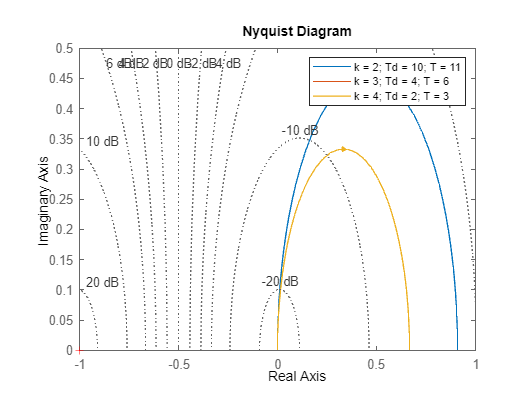


G1 = tf(licz1, mian1);
G2 = tf(licz2, mian2);
G3 = tf(licz3, mian3);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G1, plotoptions);
hold on
nyquist(G2, plotoptions);
nyquist(G3, plotoptions);
hold off
grid on
legend('k = 2; Td = 10; T = 11', 'k = 3; Td = 4; T = 6', 'k = 4; Td = 2; T = 3')

### Obiekt inercyjny I rzędu z opóźnieniem

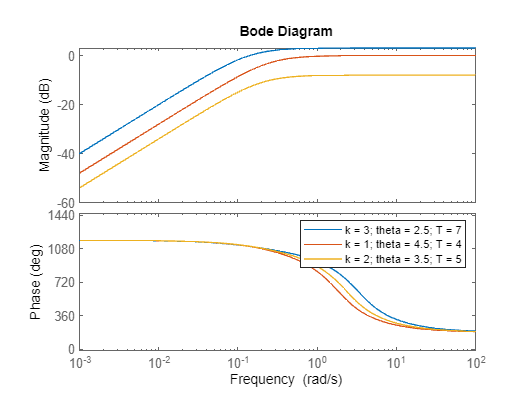

n = 5;

k1 = 3;
k2 = 1;
k3 = 2;
T1  =7;
T2 = 4;
T3 = 5;
theta1 = 2.5;
theta2 = 4.5;
theta3 = 3.5;

[del_l1, del_m1] = pade(theta1, n);
[del_l2, del_m2] = pade(theta2, n);
[del_l3, del_m3] = pade(theta3, n);

mian1 = [T1, 1];
mian2 = [T2, 1];
mian3 = [T3, 1];

[licz_d1, mian_d1] = series(del_l1, del_m1, licz1, mian1);
[licz_d2, mian_d2] = series(del_l2, del_m2, licz2, mian2);
[licz_d3, mian_d3] = series(del_l3, del_m3, licz3, mian3);

bode(licz_d1, mian_d1)
hold on
bode(licz_d2, mian_d2)
bode(licz_d3, mian_d3)
hold off
legend('k = 3; theta = 2.5; T = 7', 'k = 1; theta = 4.5; T = 4', 'k = 2; theta = 3.5; T = 5')

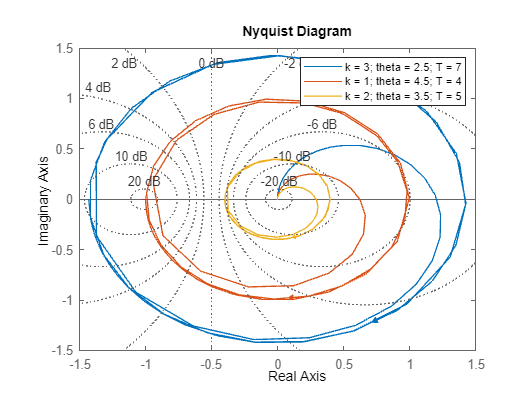


G1 = tf(licz_d1, mian_d1);
G2 = tf(licz_d2, mian_d2);
G3 = tf(licz_d3, mian_d3);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G1, plotoptions);
hold on
nyquist(G2, plotoptions);
nyquist(G3, plotoptions);
hold off
grid on
legend('k = 3; theta = 2.5; T = 7', 'k = 1; theta = 4.5; T = 4', 'k = 2; theta = 3.5; T = 5')

### Wnioski

Charakterystyki częstotliwościowe amplitudowo-fazowe oraz modułu i fazy różnią się znacznie dla poszczególnych typów obiektów. Parametry tych obiektów również mają wpływ na wygląd charakterystyk. Szczególnie charakterystycznie wyglądają wykresy Nyquista dla obiektu całkującego z inercją I rzędu i obiektu inercyjnego I rzędu z opóźnieniem.